4. Datele urmatoare dau populatia SUA (in milioane) determinata la recensaminte de US Census, intre anii 1900 si 2010. Dorim sa modelam populatia si sa o estimam pentru anii 1975 si 2010.

Modelati populatia printr-un model polinomial de gradul 3


$$y=c_0+c_1t+c_2t^2+c_3t^3$$


si printr-un model exponential


$$y=Ke^{\lambda t}$$


y = [75995 91972 105710 123200 131670 150700 179320 203210 226510 249630 281420 308790]';
t = (1900:10:2010)';
x = (1890:1:2030)';

Potrivire polinomiala:

s = (t - 1950) / 50;
xs = (x - 1950) / 50;
cs = polyfit(s, y, 3);
zs = polyval(cs, xs);
est = polyval(cs, [(1975 - 1950) / 50, (2010 - 1950) / 50])

est = 	1.0e+05 *

    2.1255    3.0973


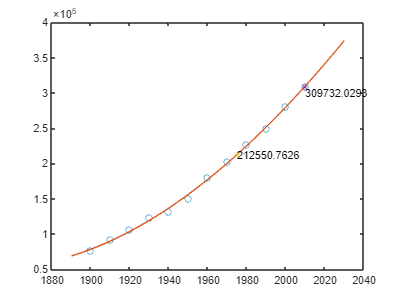

plot(t, y, 'o', x, zs, '-', 1975, est(1), '*', 2010, est(2),"*");
text(1975, est(1), num2str(est(1)));
text(2010, est(2)-1e4, num2str(est(2)));

Potrivire exponentiala:

$y=Ke^{\lambda t} \leftrightarrow ln(y)=ln(K)+\lambda t$ => Potrivirea exponentiala e echivalenta cu MCMMP pentru $(t, ln(y))$. Pentru stabilitate numerica, se va folosi in calcul $ln\left(\frac{y}{y_1}\right)$, impreuna cu transformarile inverse de rigoare.

% Potrivire exponentiala:
cs = polyfit(s, log(y/y(1)), 1);
k=exp(cs(1))

k = 1.8772

lambda = cs(2)

lambda = 0.6931

zs = y(1)*k*exp(cs(2)*xs); 
est = y(1)*k*exp(cs(2)*([(1975 - 1950) / 50, (2010 - 1950) / 50]))

est = 	1.0e+05 *

    2.0174    3.2772


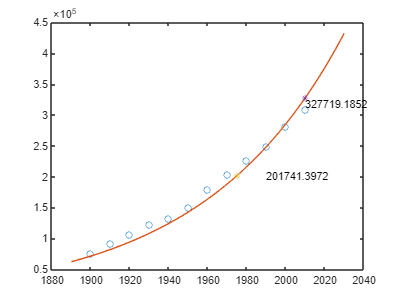

plot(t, y, 'o', x, zs, '-', 1975, est(1), '*', 2010, est(2), '*');
text(1990, est(1), num2str(est(1)));
text(2010, est(2)-1e4, num2str(est(2)));